clear

%front spar
OffsetFs=2.58;
PFs=90136*1.5*sin(OffsetFs/2)/2; %tangential
QFs=90136*1.5*cos(OffsetFs/2)/2; %radial
TFs=0; %torque

[solFs,massFs,a]=heavyframe1(PFs,QFs,TFs,OffsetFs)

Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    b: 0.2628
    h: 0.0994
    t: 0.0120


yieldstress = 276000000

shearyieldstress = 204000000

yieldmoment = 2.7570e+08

yield = 1.2474e+07

shear = 8.1379e+06

mass = 100.4731

area = 0.0075

solFs = struct with fields:
    b: 0.2628
    h: 0.0994
    t: 0.0120


massFs = 100.4731

a =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


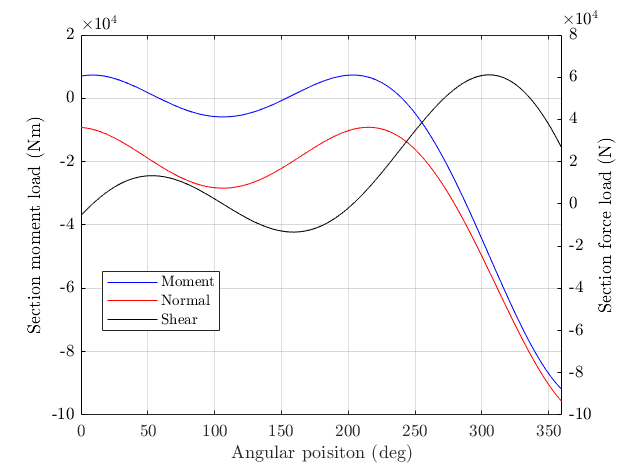

saveas(a,'fs.png')


%rear spar
OffsetRs=2.58;
PRs=41242*1.5*sin(OffsetRs/2)/2; %tangential
QRs=41242*1.5*cos(OffsetRs/2)/2; %radial
TRs=0; %torque

[solRs,massRs,a]=heavyframe1(PRs,QRs,TRs,OffsetRs)

Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



sol = struct with fields:
    b: 0.1424
    h: 0.0985
    t: 0.0098


yieldstress = 276000000

shearyieldstress = 204000000

yieldmoment = 2.7347e+08

yield = 1.1372e+07

shear = 7.4187e+06

mass = 54.0910

area = 0.0038

solRs = struct with fields:
    b: 0.1424
    h: 0.0985
    t: 0.0098


massRs = 54.0910

a =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


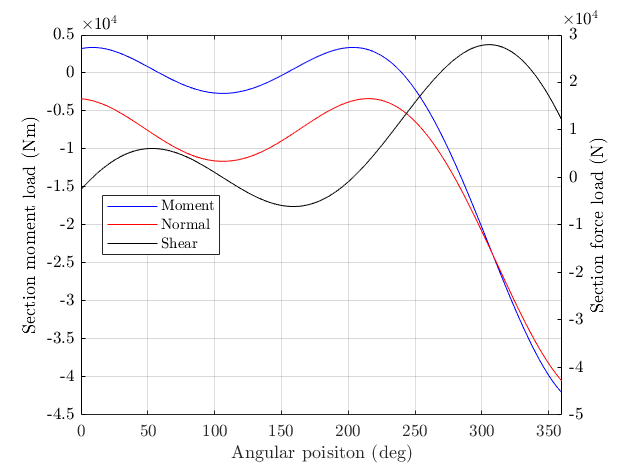

saveas(a,'rs.png')


%nose gear
PN=0;
QN=41242*1.5;
TN=0;

[solN,massN,a]=heavyframe2(PN,QN,TN)

Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    b: 0.0796
    h: 0.1000
    t: 0.0050


yieldstress = 276000000

shearyieldstress = 204000000

yieldmoment = 2.7617e+08

yield = 2.0722e+07

shear = 2.3865e+07

mass = 19.2303

area = 0.0013

solN = struct with fields:
    b: 0.0796
    h: 0.1000
    t: 0.0050


massN = 19.2303

a =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


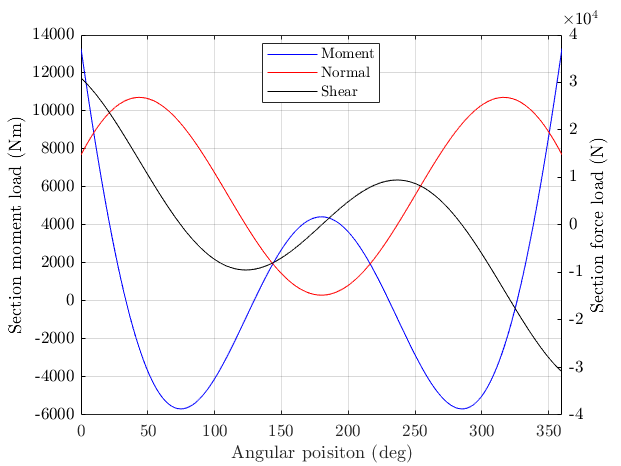

saveas(a,'ng.png')


%engines
OffsetE=3.14;
PE=209*9.81*1.5*sin(OffsetE/2)/2; %tangential
QE=209*9.81*1.5*cos(OffsetE/2)/2; %radial
TE=209*9.81*1.165; %torque

[solE,massE,a]=heavyframe1(PE,QE,TE,OffsetE)

Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    b: 0.0159
    h: 0.0918
    t: 0.0050


yieldstress = 276000000

shearyieldstress = 204000000

yieldmoment = 2.7586e+08

yield = 2.7015e+06

shear = 3.6785e+06

mass = 9.4129

area = 6.1920e-04

solE = struct with fields:
    b: 0.0159
    h: 0.0918
    t: 0.0050


massE = 9.4129

a =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


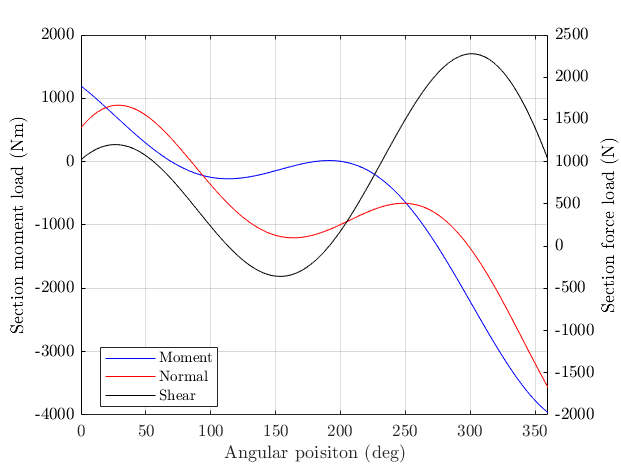

saveas(a,'e.png')


%tailplane
PT=1179*1.5;
QT=2413*1.5;
TT=2413*1.055*1.5;

[solt,massT,a]=heavyframe2(PT,QT,TT)

Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    b: 0.0131
    h: 0.0756
    t: 0.0050


yieldstress = 276000000

shearyieldstress = 204000000

yieldmoment = 2.7586e+08

yield = 7.8916e+06

shear = 6.6929e+06

mass = 7.7560

area = 5.1000e-04

solt = struct with fields:
    b: 0.0131
    h: 0.0756
    t: 0.0050


massT = 7.7560

a =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


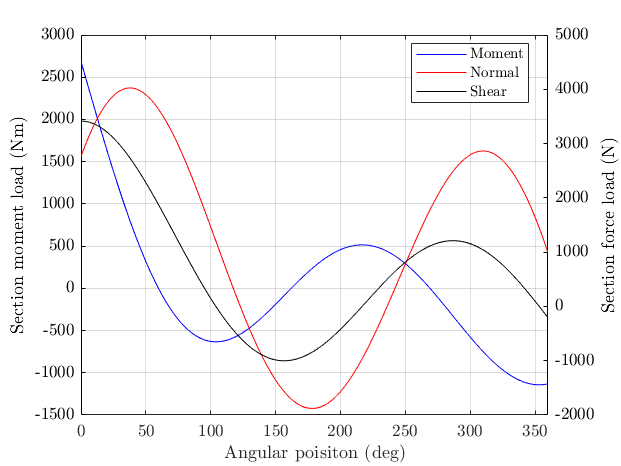

saveas(a,'tp.png')


mass=massFs+massRs+massN+massE+massT

mass = 190.9634

function [sol,mass,a]=heavyframe1(P,Q,T,Offset)

theta=linspace(0,2*pi,360);
theta2=theta+Offset;
thetadeg=linspace(0,360,360);
diameter=1.8;
radius=diameter/2;
density=2700;

yieldstress=276000000;
shearyieldstress=204000000;

Mp=P*radius*(3*sin(theta)/2+(pi-theta).*(cos(theta)-1))/(2*pi)-P*radius*(3*sin(theta2)/2+(pi-theta2).*(cos(theta2)-1))/(2*pi);
Np=P*(sin(theta)/2+(pi-theta).*cos(theta))/(2*pi)-P*(sin(theta2)/2+(pi-theta2).*cos(theta2))/(2*pi);
Sp=P*((pi-theta).*sin(theta)-1-cos(theta)/2)/(2*pi)-P*((pi-theta2).*sin(theta2)-1-cos(theta2)/2)/(2*pi);

Mq=Q*radius*(cos(theta)/2-(pi-theta).*sin(theta)+1)/(2*pi)+Q*radius*(cos(theta2)/2-(pi-theta2).*sin(theta2)+1)/(2*pi);
Nq=Q*(3*cos(theta)/2+(pi-theta).*sin(theta))/(2*pi)+Q*(3*cos(theta2)/2+(pi-theta2).*sin(theta2))/(2*pi);
Sq=Q*((pi-theta).*cos(theta)-sin(theta)/2)/(2*pi)+Q*((pi-theta2).*cos(theta2)-sin(theta2)/2)/(2*pi);

Mt=T*(pi-2*sin(theta)-theta)/(2*pi);
Nt=T*(3*cos(theta)/2+(pi-theta).*sin(theta))/(2*pi*radius);
St=T*(1+2*cos(theta))/(2*pi*radius);

M=Mp+Mq+Mt;
N=Np+Nq+Nt;
S=Sp+Sq+St;

a=figure;
grid on
hold on
box on
xlim([0,360]);
xlabel('Angular poisiton (deg)','interpreter','latex')

yyaxis left
plot(thetadeg,M,'b');
ylabel('Section moment load (Nm)','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
set(gca,'YColor','k')

yyaxis right
plot(thetadeg,N,'r');
plot(thetadeg,S,'-k');
ylabel('Section force load (N)','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
set(gca,'YColor','k')

legend('Moment','Normal','Shear','Location','best','interpreter','latex');

MaxNormal=max(abs(N));
MaxShear=max(abs(S));
MaxMoment=max(abs(M));

%optimization

framemass = optimproblem('ObjectiveSense','min');

bframe = optimvar('b','LowerBound',0.01,'UpperBound',0.5);
hframe = optimvar('h','LowerBound',0.01,'UpperBound',0.10);
tframe = optimvar('t','LowerBound',0.005,'UpperBound',0.02);

framemass.Constraints.cons1 = MaxMoment*(hframe/2)/(tframe*(hframe^3/12+bframe*tframe^2/6+bframe*hframe^2/2)) <= yieldstress;
framemass.Constraints.cons2 = MaxNormal/(tframe*(2*bframe+hframe)) <= yieldstress;
framemass.Constraints.cons3 = MaxShear/(tframe*(2*bframe+hframe)) <= shearyieldstress;

framemass.Objective = tframe*(2*bframe+hframe);

sol0.b=0.01;
sol0.h=0.01;
sol0.t=0.005;

sol=solve(framemass,sol0)

yieldstress
shearyieldstress

yieldmoment=MaxMoment*(sol.h/2)/(sol.t*(sol.h^3/12+sol.b*sol.h^2/2)) %<= yieldstress
yield=MaxNormal/(sol.t*(2*sol.b+sol.h)) %<= yieldstress
shear=MaxShear/(sol.t*(2*sol.b+sol.h)) %<= shearyieldstress

mass=density*(2*pi*((diameter/2)^2-(diameter/2-sol.b)^2)*sol.t+pi*((diameter/2)^2-(diameter/2-sol.t)^2)*sol.h)
area=sol.t*(2*sol.b+sol.h)
end

function [sol,mass,a]=heavyframe2(P,Q,T)

theta=linspace(0,2*pi,360);

thetadeg=linspace(0,360,360);
diameter=1.8;
radius=diameter/2;
density=2700;

yieldstress=276000000;
shearyieldstress=204000000;

Mp=P*radius*(3*sin(theta)/2+(pi-theta).*(cos(theta)-1))/(2*pi);
Np=P*(sin(theta)/2+(pi-theta).*cos(theta))/(2*pi);
Sp=P*((pi-theta).*sin(theta)-1-cos(theta)/2)/(2*pi);

Mq=Q*radius*(cos(theta)/2-(pi-theta).*sin(theta)+1)/(2*pi);
Nq=Q*(3*cos(theta)/2+(pi-theta).*sin(theta))/(2*pi);
Sq=Q*((pi-theta).*cos(theta)-sin(theta)/2)/(2*pi);

Mt=T*(pi-2*sin(theta)-theta)/(2*pi);
Nt=T*(3*cos(theta)/2+(pi-theta).*sin(theta))/(2*pi*radius);
St=T*(1+2*cos(theta))/(2*pi*radius);

M=Mp+Mq+Mt;
N=Np+Nq+Nt;
S=Sp+Sq+St;

a=figure;
grid on
hold on
box on
xlim([0,360]);
xlabel('Angular poisiton (deg)','interpreter','latex')

yyaxis left
plot(thetadeg,M,'b');
ylabel('Section moment load (Nm)','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
set(gca,'YColor','k')

yyaxis right
plot(thetadeg,N,'r');
plot(thetadeg,S,'-k');
ylabel('Section force load (N)','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
set(gca,'YColor','k')

legend('Moment','Normal','Shear','Location','best','interpreter','latex');
saveas(a,'tp.png')


MaxNormal=max(abs(N));
MaxShear=max(abs(S));
MaxMoment=max(abs(M));

%optimization

framemass = optimproblem('ObjectiveSense','min');

bframe = optimvar('b','LowerBound',0.01,'UpperBound',0.5);
hframe = optimvar('h','LowerBound',0.01,'UpperBound',0.10);
tframe = optimvar('t','LowerBound',0.005,'UpperBound',0.02);

framemass.Constraints.cons1 = MaxMoment*(hframe/2)/(tframe*(hframe^3/12+bframe*tframe^2/6+bframe*hframe^2/2)) <= yieldstress;
framemass.Constraints.cons2 = MaxNormal/(tframe*(2*bframe+hframe)) <= yieldstress;
framemass.Constraints.cons3 = MaxShear/(tframe*(2*bframe+hframe)) <= shearyieldstress;

framemass.Objective = tframe*(2*bframe+hframe);

sol0.b=0.01;
sol0.h=0.01;
sol0.t=0.005;

sol=solve(framemass,sol0)

yieldstress
shearyieldstress

yieldmoment=MaxMoment*(sol.h/2)/(sol.t*(sol.h^3/12+sol.b*sol.h^2/2)) %<= yieldstress
yield=MaxNormal/(sol.t*(2*sol.b+sol.h)) %<= yieldstress
shear=MaxShear/(sol.t*(2*sol.b+sol.h)) %<= shearyieldstress

mass=density*(2*pi*((diameter/2)^2-(diameter/2-sol.b)^2)*sol.t+pi*((diameter/2)^2-(diameter/2-sol.t)^2)*sol.h)
area=sol.t*(2*sol.b+sol.h)
end

